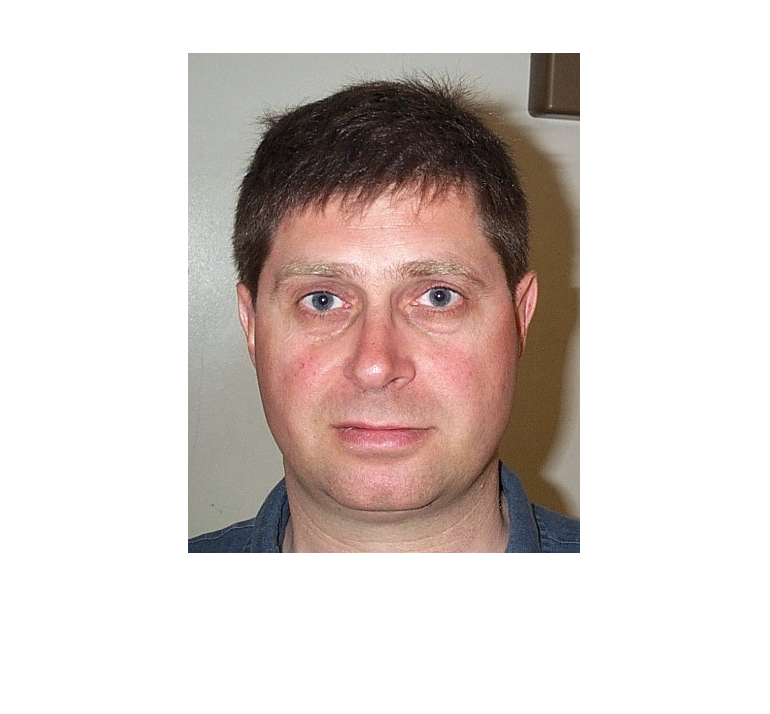

addpath('Functions');
addpath('Images');
% Main-file

% PART 1 (purpose to find eyes)

% Load dataset
test1 = imread("Images\DB1\db1_01.jpg");
imshow(test1)

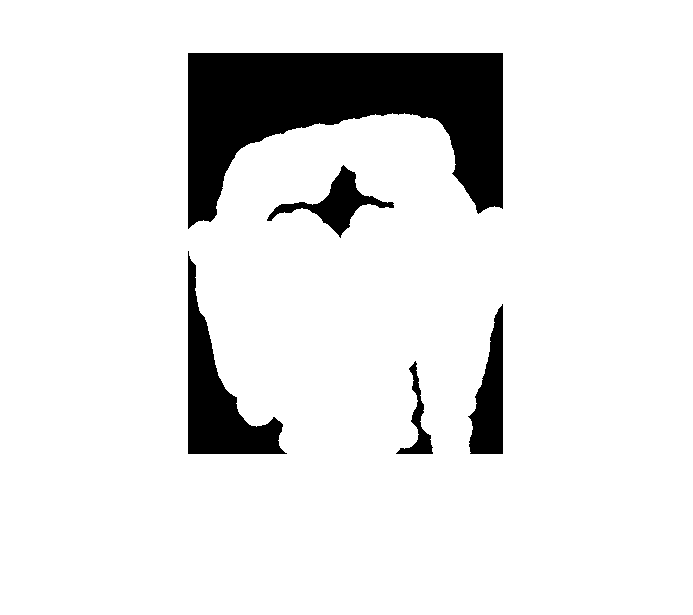


% Get the size of the original image
[rows, cols, ~] = size(test1);

% Calculate the cropping margins (10% on each side)
cropMarginRows = round(0.1 * rows);
cropMarginCols = round(0.1 * cols);

% Crop the image
test1 = imcrop(test1, [cropMarginCols, cropMarginRows, cols - 2*cropMarginCols, rows - 2*cropMarginRows]);


%%%%%% Lighting compensation - Gray World & White Patch %%%%%
% GW = GrayWorld(test1);
% imshow(GW)
WP = WhitePatch(test1);
% imshow(WP)


%%%%%%% Color Space + FaceMask  %%%%%%%%%%%%%%%%%%%%%
testFM = FaceMask(WP);
imshow(testFM)

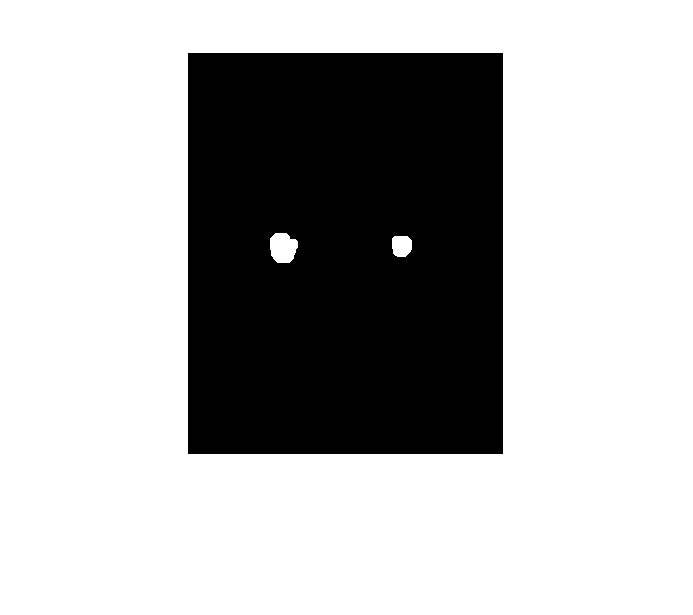


%%%%%%%%%%%% Eye map: Chrominance & Luminance %%%%%%%%%%%%
binaryEyeMap = EyeMap(WP);
%imshow(binaryEyeMap)


%%%%%%%%%%%%%% Tidigare kod för att hitta circles från ansikte %%%
%[FMEM, circle, randii] = EyeFilter(WP);
[FMEM] = EyeFilter(WP);
imshow(FMEM)

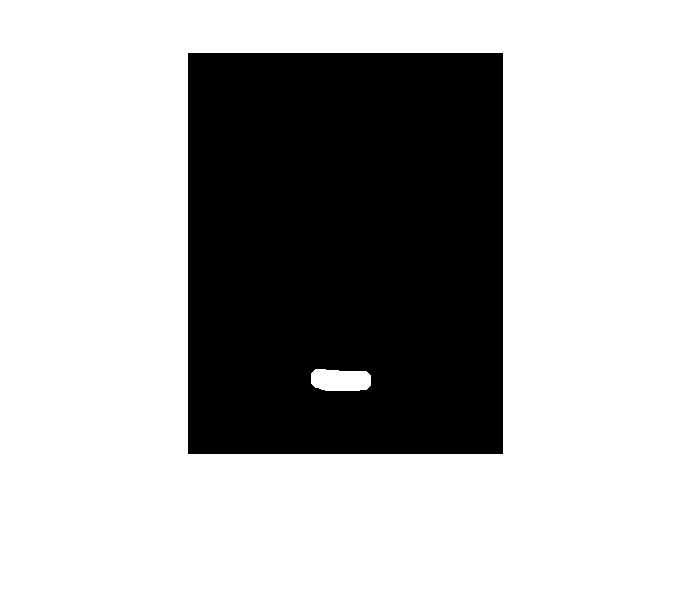


% circle;
% centersStrong5 = circle(1:2,:);
% radiiStrong5 = randii(1:2);
% viscircles(centersStrong5, radiiStrong5,'EdgeColor','b');

% BW1 = edge(FMEM,'sobel');
% imshow(BW1)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



%%%%%%%%%%%%% Mouth map? %%%%%%%%%%%%%%%%%%%%%%%%%
[mouth_Map, mouth_center] = MouthMap(WP);
imshow(mouth_Map)


disp('Mouth Center Coordinates:');

Mouth Center Coordinates:


disp(mouth_center)

  153.2629  327.8198



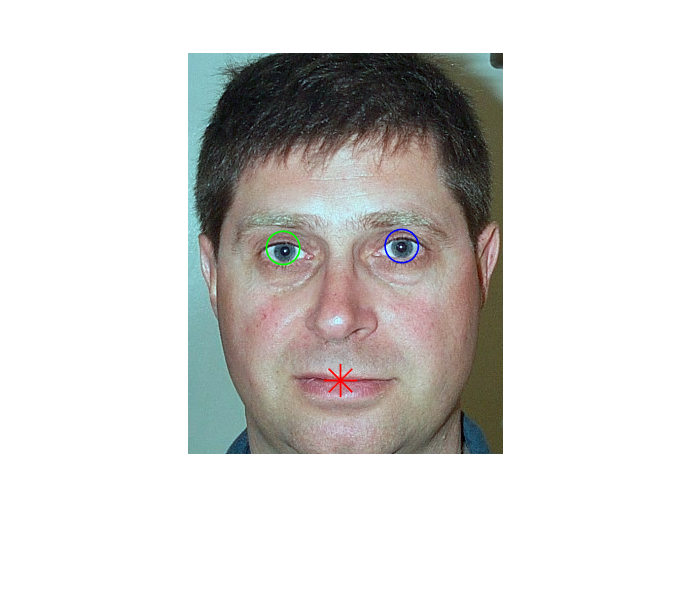


% %%%%%%%%%%%%% Check if mouth_center is not empty %%%%%%%%%%
% if ~isempty(mouth_center)
%     hold on;
%     
%  %  Extract x and y coordinates from mouth_center
%     x_mouth = mouth_center(1);
%     y_mouth = mouth_center(2);
%     
%  %  Assuming the width and height of the rectangle
%     width = 100;
%     height = 60;
%     
%   % Draw a rectangle around the detected mouth region
%     rectangle('Position', [x_mouth-width/2, y_mouth-height/2, width, height], 'EdgeColor', 'r', 'LineWidth', 2);
%     
%     hold off;
% end

%%%%%%%%%%%%%% Face Boundary %%%%%%%%%%%%%%%%%%%%%%%% 
% Assuming you have the input image 'img'
[eyes, mouth] = face_boundary(WP);

% Display the original image
figure;
imshow(WP);
hold on;

% Plot the mouth center
plot(mouth(1), mouth(2), 'r*', 'MarkerSize', 10);

% Plot the detected eyes
if ~isempty(eyes)
    plot(eyes(1, 1), eyes(1, 2), 'go', 'MarkerSize', 10); % Left eye
    plot(eyes(2, 1), eyes(2, 2), 'bo', 'MarkerSize', 10); % Right eye
end

hold off;

eyes

eyes =    95.6104  195.4044
  214.2216  193.5189


mouth

mouth =   153.2629  327.8198


%%%%%%%%%%%%%%% Detect Face %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Call detect_face to get the combined binary mask
%combined_mask = detect_face(WP);
%imshow(combined_mask)




%%%%%%%%%%%%%%% Looping through all the images %%%%%%%%%%%%%%%%%%%

% Specify the folder containing the images
% folderPath = 'Images\DB1\';
% 
% % Get a list of all image files in the folder
% imageFiles = dir(fullfile(folderPath, '*.jpg')); % Change the extension as needed

% % Loop through each image file
% for i = 1:length(imageFiles)
%     % Read the image
%     imagePath = fullfile(folderPath, imageFiles(i).name);
%     img = imread(imagePath);
% 
%     % Apply the GrayWorld & MouthMap/FaceMask function
%     GW = WhitePatch(img);
%     % mouthMapResult = MouthMap(GW);
% 
%     % Display the original image and the processed result
%     figure;
%     subplot(1, 2, 1);
%     imshow(img);
%     title('Original Image');
% 
%     subplot(1, 2, 2);
%     imshow(mouthMapResult);
%     title('Thresholded Mouth Map');
% 
%     % Pause to allow for viewing before moving to the next image
%     pause(2);
%     close all;  % Close the figure window for the next iteration
% end